## FFT demo - comparing FFT and dot product

Start by making a discrete time vector... 

clear
time = 0.001:0.001:1; % one second of discrete time, sampled at 1000 Hz

now, a Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

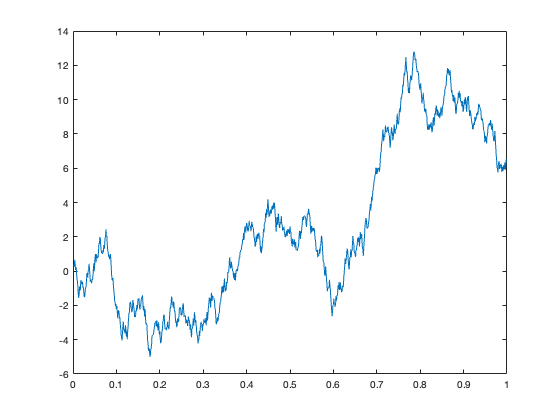

temp1 = rand(size(time))-.5; % zero-centered white nois
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white nois
figure
plot(time, brownsig),title('The Brownian noise') 

Now we make 3 simple signals, to be added to the brownian noise.

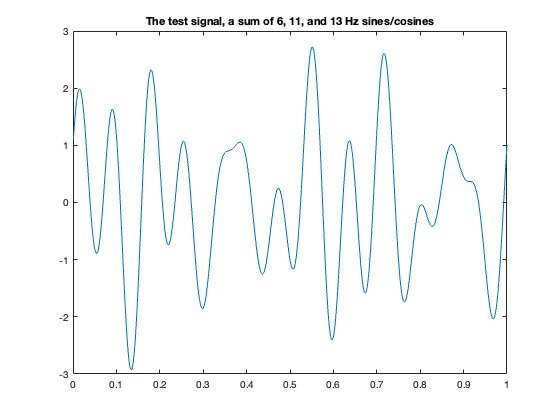

Sin6Hz = sin(2*pi*time*6); % a 6 Hz sine wave
Cos11Hz = cos(2*pi*time*11); % a 11 Hz cosine wave
Sin13Hz = sin(2*pi*time*13); % a 13 Hz sine wave

sumsig = Sin6Hz + Cos11Hz + Sin13Hz; 
figure
plot(time, sumsig), title('The test signal, a sum of 6, 11, and 13 Hz sines/cosines') 

The sum of the three test signals, two sinoids, one cosinoid is now added to the Brownian noise

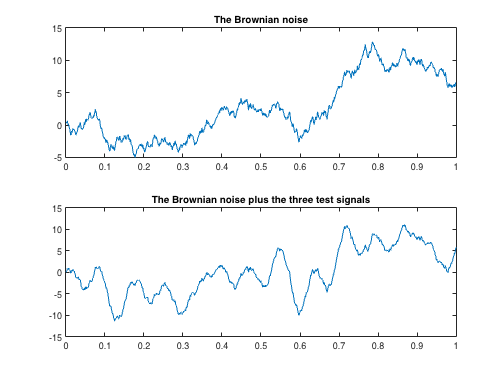

testsig1  = brownsig-mean(brownsig); % zero-centered Brownian noise
testsig = testsig1 + sumsig.*2; % multiply sum of sine/cosine signals by 2 to make it more prominent
figure
subplot(2,1,1), plot(time, brownsig), title('The Brownian noise') % the real part
subplot(2,1,2), plot(time, testsig), title('The Brownian noise plus the three test signals') 

Now, the Discrete Fourier Transform, resulting in a complex spectrum with real (cosine-base) and imaginary (sine-base) components

complexspectrum = fft(testsig);

We have a 1-sec segment, which means the frequency resolution is 1 Hz; sampled at 1000 Hz, the maximum axis goes from 0 Hz to 500 Hz. 

faxis = 0:500; 

Plot the resulting spectra, one for the real part, one for the imaginary part, and the (combined) amplitude spectrum. We plot only frequencies between 0 and 30 Hz

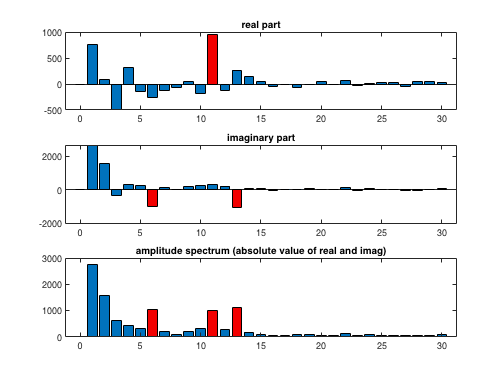

figure
subplot(3,1,1), b1 = bar(faxis(1:31), real(complexspectrum(1:31))); title('real part') % the real part
b1.FaceColor = 'flat'; b1.CData(12,:) = [.95 0 0]; % this is just to make the seed frequencies red

subplot(3,1,2), b2 = bar(faxis(1:31), imag(complexspectrum(1:31))); title('imaginary part') % the imaginary part
b2.FaceColor = 'flat'; b2.CData([7 14],:) = [.95 0 0; .95 0 0]; % this is just to make the seed frequencies red

subplot(3,1,3), b3 = bar(faxis(1:31), abs(complexspectrum(1:31))); title('amplitude spectrum (absolute value of real and imag)')% the absolute value
b3.FaceColor = 'flat'; b3.CData([7 12 14],:) = [.95 0 0; .95 0 0; .95 0 0]; % this is just to make the seed frequencies red

Now we run the DFT ourselves, doing the dot product of each cosine template with the data, this should look like the real part of the DFT

figure
for x = 1:30
    cosdot(x) = testsig*cos(time*2*pi*x)'; 
    subplot(2,1,1), plot(time, sin(time*2*pi*x))
    subplot(2,1,2), hold on, bar(x,cosdot(x), 'k'), if x==11, bar(x,cosdot(x), 'r'), end
    pause(1)
end


Now we run the DFT again, doing the dot product of each sine template with the data

figure
for x = 1:30
    sindot(x) = testsig*sin(time*2*pi*x)'; 
    subplot(2,1,1), plot(time, sin(time*2*pi*x))
    subplot(2,1,2), hold on, bar(x,sindot(x), 'k'), if ismember(x, [6 13]), bar(x,sindot(x), 'r'), end
    pause(1)
end

Plot the resulting spectra

dotprodspec  = cosdot + 1i*sindot; 
figure
b4 = bar(1:30, abs(dotprodspec)); title('amplitude spectrum (absolute value of real and imag)')% the absolute value
b4.FaceColor = 'flat'; b4.CData([6 11 13],:) = [.95 0 0; .95 0 0; .95 0 0]; % this is just to make the seed frequencies red